## Define Parameters

Length of the rod $L$:

L = 1;

Integration time $T$:

T = 0.5;

Parameters of the steel rod: density $\rho$, radius $R$ and Young's modulus $E$:

rho = 7860;
R = 1e-2;
E = 210e9;
rod_par = [rho, R, E];
D = R^2;
C = E*R^2/rho;

Spatial $h$ and temporal $\tau$ steps

h = 0.02;
tau = 0.0001;

% Calculate the number of spatial steps
Nx = ceil(L / h) + 1;
% Adjust step h
h = L / (Nx - 1)

h = 0.0200

% Calculate the number of temporal steps
Nt = ceil(T / tau) + 1;
% Adjust step h
tau = T / (Nt - 1)

tau = 1.0000e-04

Dimensionless parameters

nu = C * tau^2 / h^4

nu = 166.9847

mu = D / h^2

mu = 0.2500

## Initial conditions

Define initial conditions as

$u_0(x) = \frac{x}{0.1^2} \cdot \frac{1}{0.1\sqrt{2\pi}} e^{-\frac{x^2}{2 \cdot 0.1^2}}$ for $x \in [-L/2, L/2]$

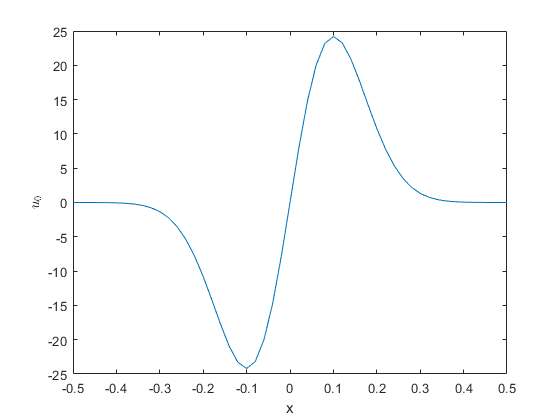

x = linspace(-L/2, L/2, Nx).';
t = linspace(0, T, Nt).';

[U_0, U_0_sigma] = GaussianDistrib_3sigma(x, [-.3, .3]);
U_0 = x.*U_0 / U_0_sigma^2;

plot(x, U_0);
xlabel('x'); ylabel('$u_0$', "Interpreter", "latex")

Also, set the first derivative w.r.t. time to be equal to zero: $\frac{\partial }{\partial t}u\left(x,0\right)=0$.

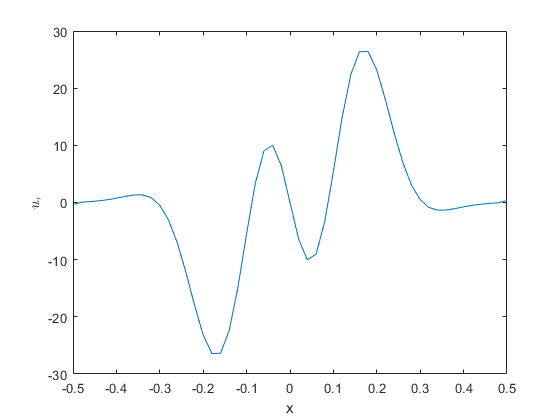

U_1 = 0 * U_0;
U_2 = u_tau_function(h, D, C, U_0);
U_tau = U_0 + U_1*tau + U_2*tau^2/2;

plot(x, U_tau);
xlabel('x'); ylabel('$u_\tau$', "Interpreter", "latex")

## Polynomial degrees

Set polynomial degrees

polynomDEG_bor = [4, 4, 8, 8];
polynomDEG_prebor = polynomDEG_bor;